make_sounds = true; % Set this to create sound examples to go with experiments
sp = sound_params();
stretch = 1.35; % for easier listening
if make_sounds
    metronome = 0:.5:6;
    identities = sp.beep_index*ones(size(metronome));
    snd = stim_maker_etime(stretch*metronome, identities, sp);
    audiowrite('sounds/metonome.wav', snd, 44100);

    event_times = [0, .4, .5, 1, 1.15, 1.5,1.7, 2, 2.3, 2.5, 3];
    times_w_lead = [0, .5, event_times+1];
    identities = [sp.beep_index, sp.beep_index, sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/distractor.wav', snd, 44100);
    
    event_times = [0, .5, 1, 1.5, 1.95, 2.45, 2.95];
    times_w_lead = [0, .5, event_times+1];
    identities = [sp.beep_index, sp.beep_index, sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/phase_shift.wav', snd, 44100);
    
    event_times = [0, .25, .5, .75, 1, 1.25, 1.75, 2];
    times_w_lead = [0, .5, event_times+1];
    identities = [sp.beep_index, sp.beep_index, sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/omission.wav', snd, 44100);
    
    event_times = [0:.125:6, 6.5, 7, 7.5, 8, 8.5];
    times_w_lead = [0, .5, event_times+1];
    unit = [sp.standard_index, sp.high_index, sp.high_index, sp.high_index]; 
    identities = [sp.beep_index, sp.beep_index, unit, unit, unit, unit, unit, unit, unit, unit, unit, unit, unit, unit, sp.standard_index*ones(1,6)];
    %identities = [sp.beep_index, sp.beep_index, sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/filled.wav', snd, 44100);
    
    event_times = [0, 0.150, 1.15, 1.65, 2.15, 2.65, 2.9, 3, 3.25, 3.5];
    times_w_lead = [0, .5, event_times+1];
    identities = [sp.beep_index, sp.beep_index, sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/veryhi_sync.wav', snd, 44100);
    
    times_w_metro = [times_w_lead, 1:.5:4.5];
    identities = [identities, sp.beep_index*ones(1,8)];
    snd = stim_maker_etime(stretch*times_w_metro, identities, sp);
    audiowrite('sounds/veryhi_sync_solution.wav', snd, 44100);

end



figure()
gauss_distribution = @(x, mean, v) exp(-.5 * ((x - mean).^ 2) ./ v)./ (sqrt(2*pi*v));


params = PIPPET_params(...
    'means_unit', [1],...
    'variance_unit', [.006],...
    'tau_unit', .5,...
    'expected_cycles', 2,...
    'expected_period', 1,...
    'event_times', [], ...
    'tau_0', 0.0000);

p = params.streams{1};

phibar_i_list = @(phibar, V) (phibar/V + p.e_means./p.e_vars)./(1/V + 1./p.e_vars);
K_i_list = @(V) 1./(1/V + 1./p.e_vars);
T_i_list = @(phibar, V) p.e_taus .* gauss_distribution(phibar, p.e_means, p.e_vars+V);

xlist = 0.5:.001:2.5;



subplot(2,1,1)

V_t = 0.02;
phi_t = 1.54;
plot(xlist, gauss_distribution(xlist, phi_t, V_t));
hold on

plot(xlist, p.expect_func(xlist))

phi_i_lst = phibar_i_list(phi_t, V_t);
K_i_lst = K_i_list(V_t)

K_i_lst =     0.0046    0.0046


T_i_lst = T_i_list(phi_t, V_t)

T_i_lst =     0.0045    0.0211


plot(xlist, T_i_lst(1)/(T_i_lst(1)+T_i_lst(2))*gauss_distribution(xlist, phi_i_lst(1), K_i_lst(1)));
plot(xlist, T_i_lst(2)/(T_i_lst(1)+T_i_lst(2))*gauss_distribution(xlist, phi_i_lst(2), K_i_lst(2)));

phi_new = p.phi_hat(phi_t, V_t);
plot(xlist, gauss_distribution(xlist, phi_new, p.V_hat(phi_new, phi_t, V_t)))


subplot(2,1,2)

V_t = 0.02;
phi_t = 1.7;
plot(xlist, gauss_distribution(xlist, phi_t, V_t));
hold on
plot(xlist, p.expect_func(xlist))

phi_i_lst = phibar_i_list(phi_t, V_t);
K_i_lst = K_i_list(V_t)

K_i_lst =     0.0046    0.0046


T_i_lst = T_i_list(phi_t, V_t)

T_i_lst =     0.0001    0.2191


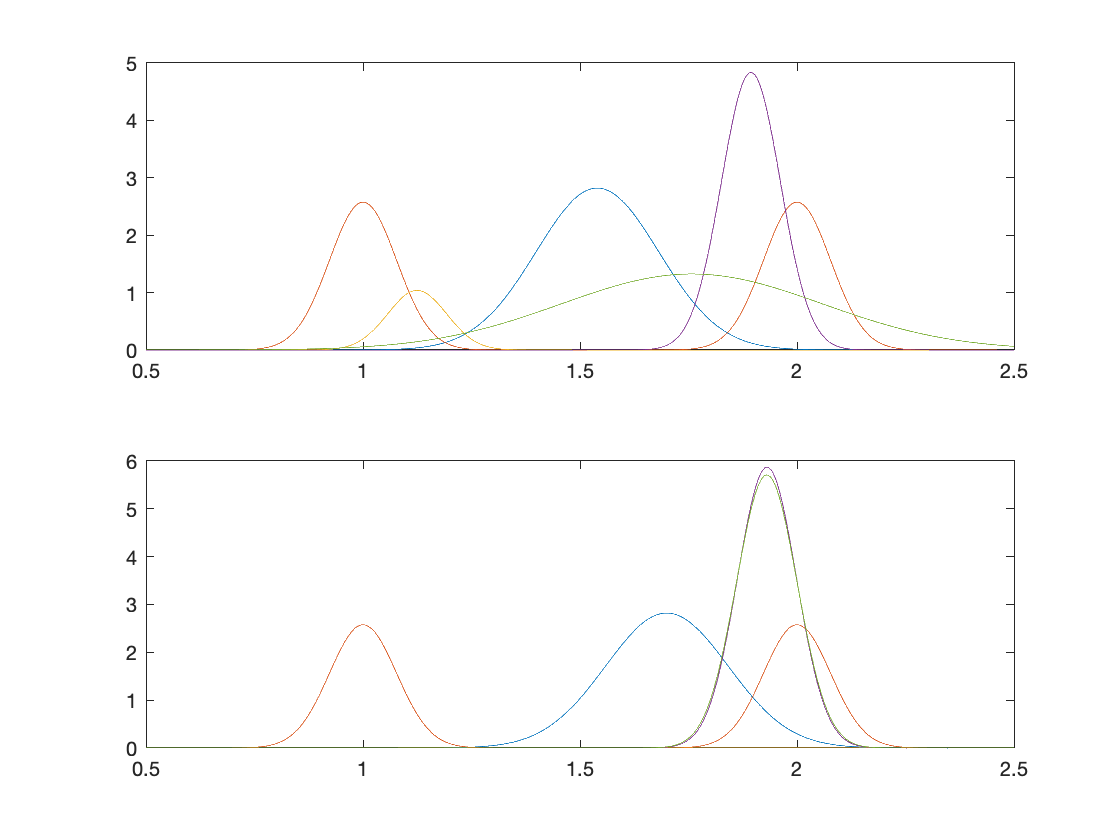

plot(xlist, T_i_lst(1)/(T_i_lst(1)+T_i_lst(2))*gauss_distribution(xlist, phi_i_lst(1), K_i_lst(1)));
plot(xlist, T_i_lst(2)/(T_i_lst(1)+T_i_lst(2))*gauss_distribution(xlist, phi_i_lst(2), K_i_lst(2)));

phi_new = p.phi_hat(phi_t, V_t);
plot(xlist, gauss_distribution(xlist, phi_new, p.V_hat(phi_new, phi_t, V_t)))